## Example: Finding the max/min of a Non-Linear Function

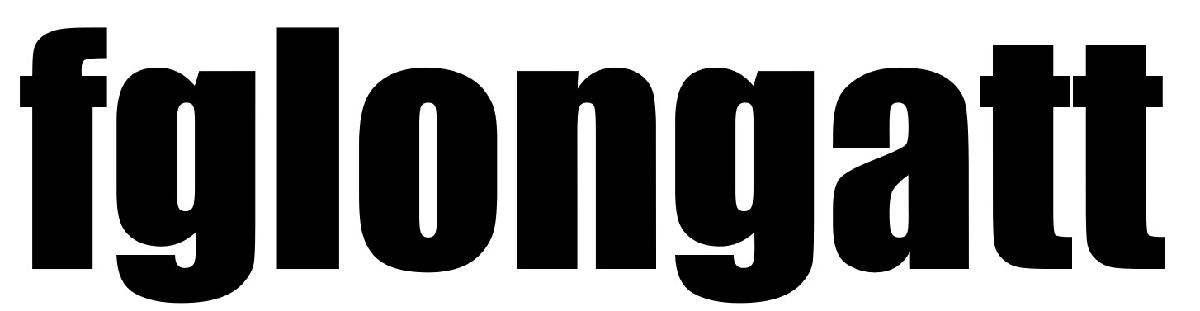  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

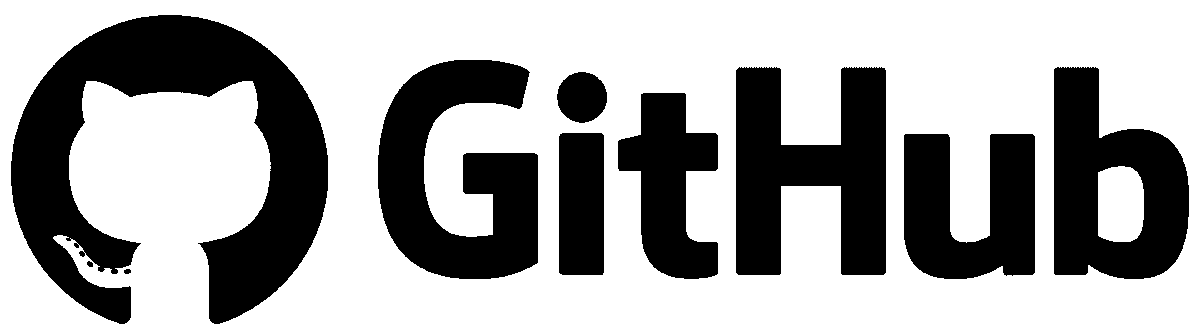 [https://github.com/fglongatt](https://github.com/fglongatt) 

Consider the following global optimisation problem:


$$\min_{x_1 } \left\lbrack \log \left(1+{\left(x_1 -\frac{4}{3}\right)}^2 +3{\left(x_1 +x_2 -x_1^3 \right)}^2 \right)\right\rbrack$$


Find the global minimum.

### Solution

clc 
clearvars

**Step 1:** Initially the symbolic mathematic in MATLAB is used to plot the three dimension: 

Define symbolic variables

syms x_1 x_2

 Define the function $f\left(x_1 \right)$

f = log(1+(x_1-4/3)^2 + 3*(x_1 + x_2 - x_1^3)^2);

Define the colour map

colormap cool

Create a three-dimensional plot showing the contours

fsurf(f,'ShowContours','on')

 Define the labels for the x, y and z axis and other properties

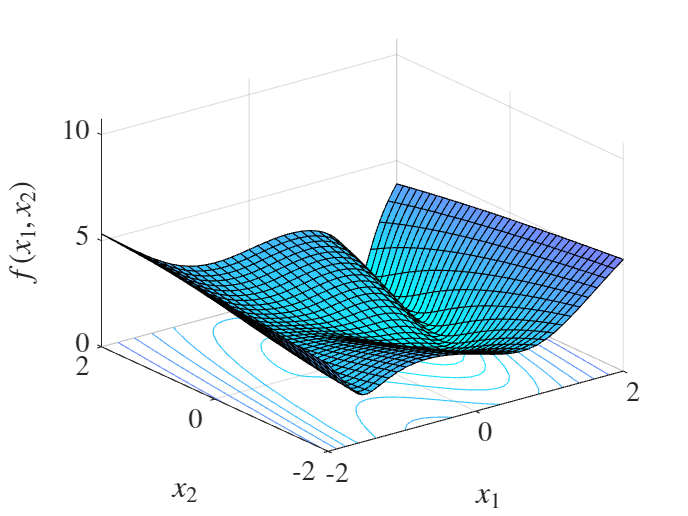

xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$f(x_1,x_2)$','Interpreter','latex')
% title_latex = ['$' latex(f) '$'];
% title(title_latex,'Interpreter','latex')
set(gca,"fontsize",12);
set(gca,'TickLabelInterpreter','latex')
xlim([-2 2])
ylim([-2 2])
grid on

**Step 2:** The objective function is created as (fun). In this case a function handle is used. A function handle is a MATLAB® data type that stores an association to a function.

fun = @(x)log(1+(x(1)-4/3)^2 +3*(x(1) + x(2) - x(1)^3)^2);     % Objective function

x0 = [0.5,0];

In this case: $x_1^0 =0\ldotp 5$ and $x_2^0 =0$

**Step 3: **Defining matrix and vector of ***the inequality constraints***:


$$\textrm{Ax}\le \mathit{\mathbf{b}}$$


In this problem, there is no inequality constraints.

A = [];
b = [];

**Step 4: **Defining matrix and vector of **the equality constraints**:


$${\mathbf{A}}_{\textrm{eq}} \mathit{\mathbf{x}}={\mathit{\mathbf{b}}}_{\textrm{eq}}$$


In this problem, there is no equality constraints.

Aeq = [];
beq = [];

**Step 5: **Executing the optimization

x = fmincon(fun,x0,A,b,Aeq,beq)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     1.3333    1.0370


**REMARK**: fmincon has more detailed configuration. More details about the configuration can be found at: [https://www.mathworks.com/help/optim/ug/fmincon.html](https://www.mathworks.com/help/optim/ug/fmincon.html) 

**Step 6: **Printing the solution:

fprintf(' x1 = %4.4f',x(1))

 X1 = 1.3333

fprintf(' x2 = %4.4f',x(2))

 X2 = 1.0370

Be part of our community 

 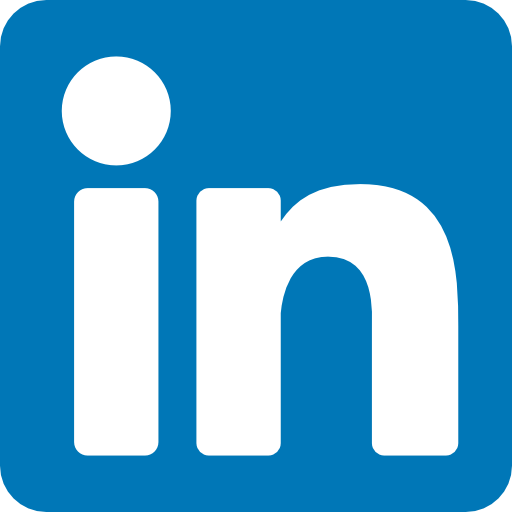 [https://www.linkedin.com/in/francisco-gonzalez-longatt/](https://www.linkedin.com/in/francisco-gonzalez-longatt/) 

 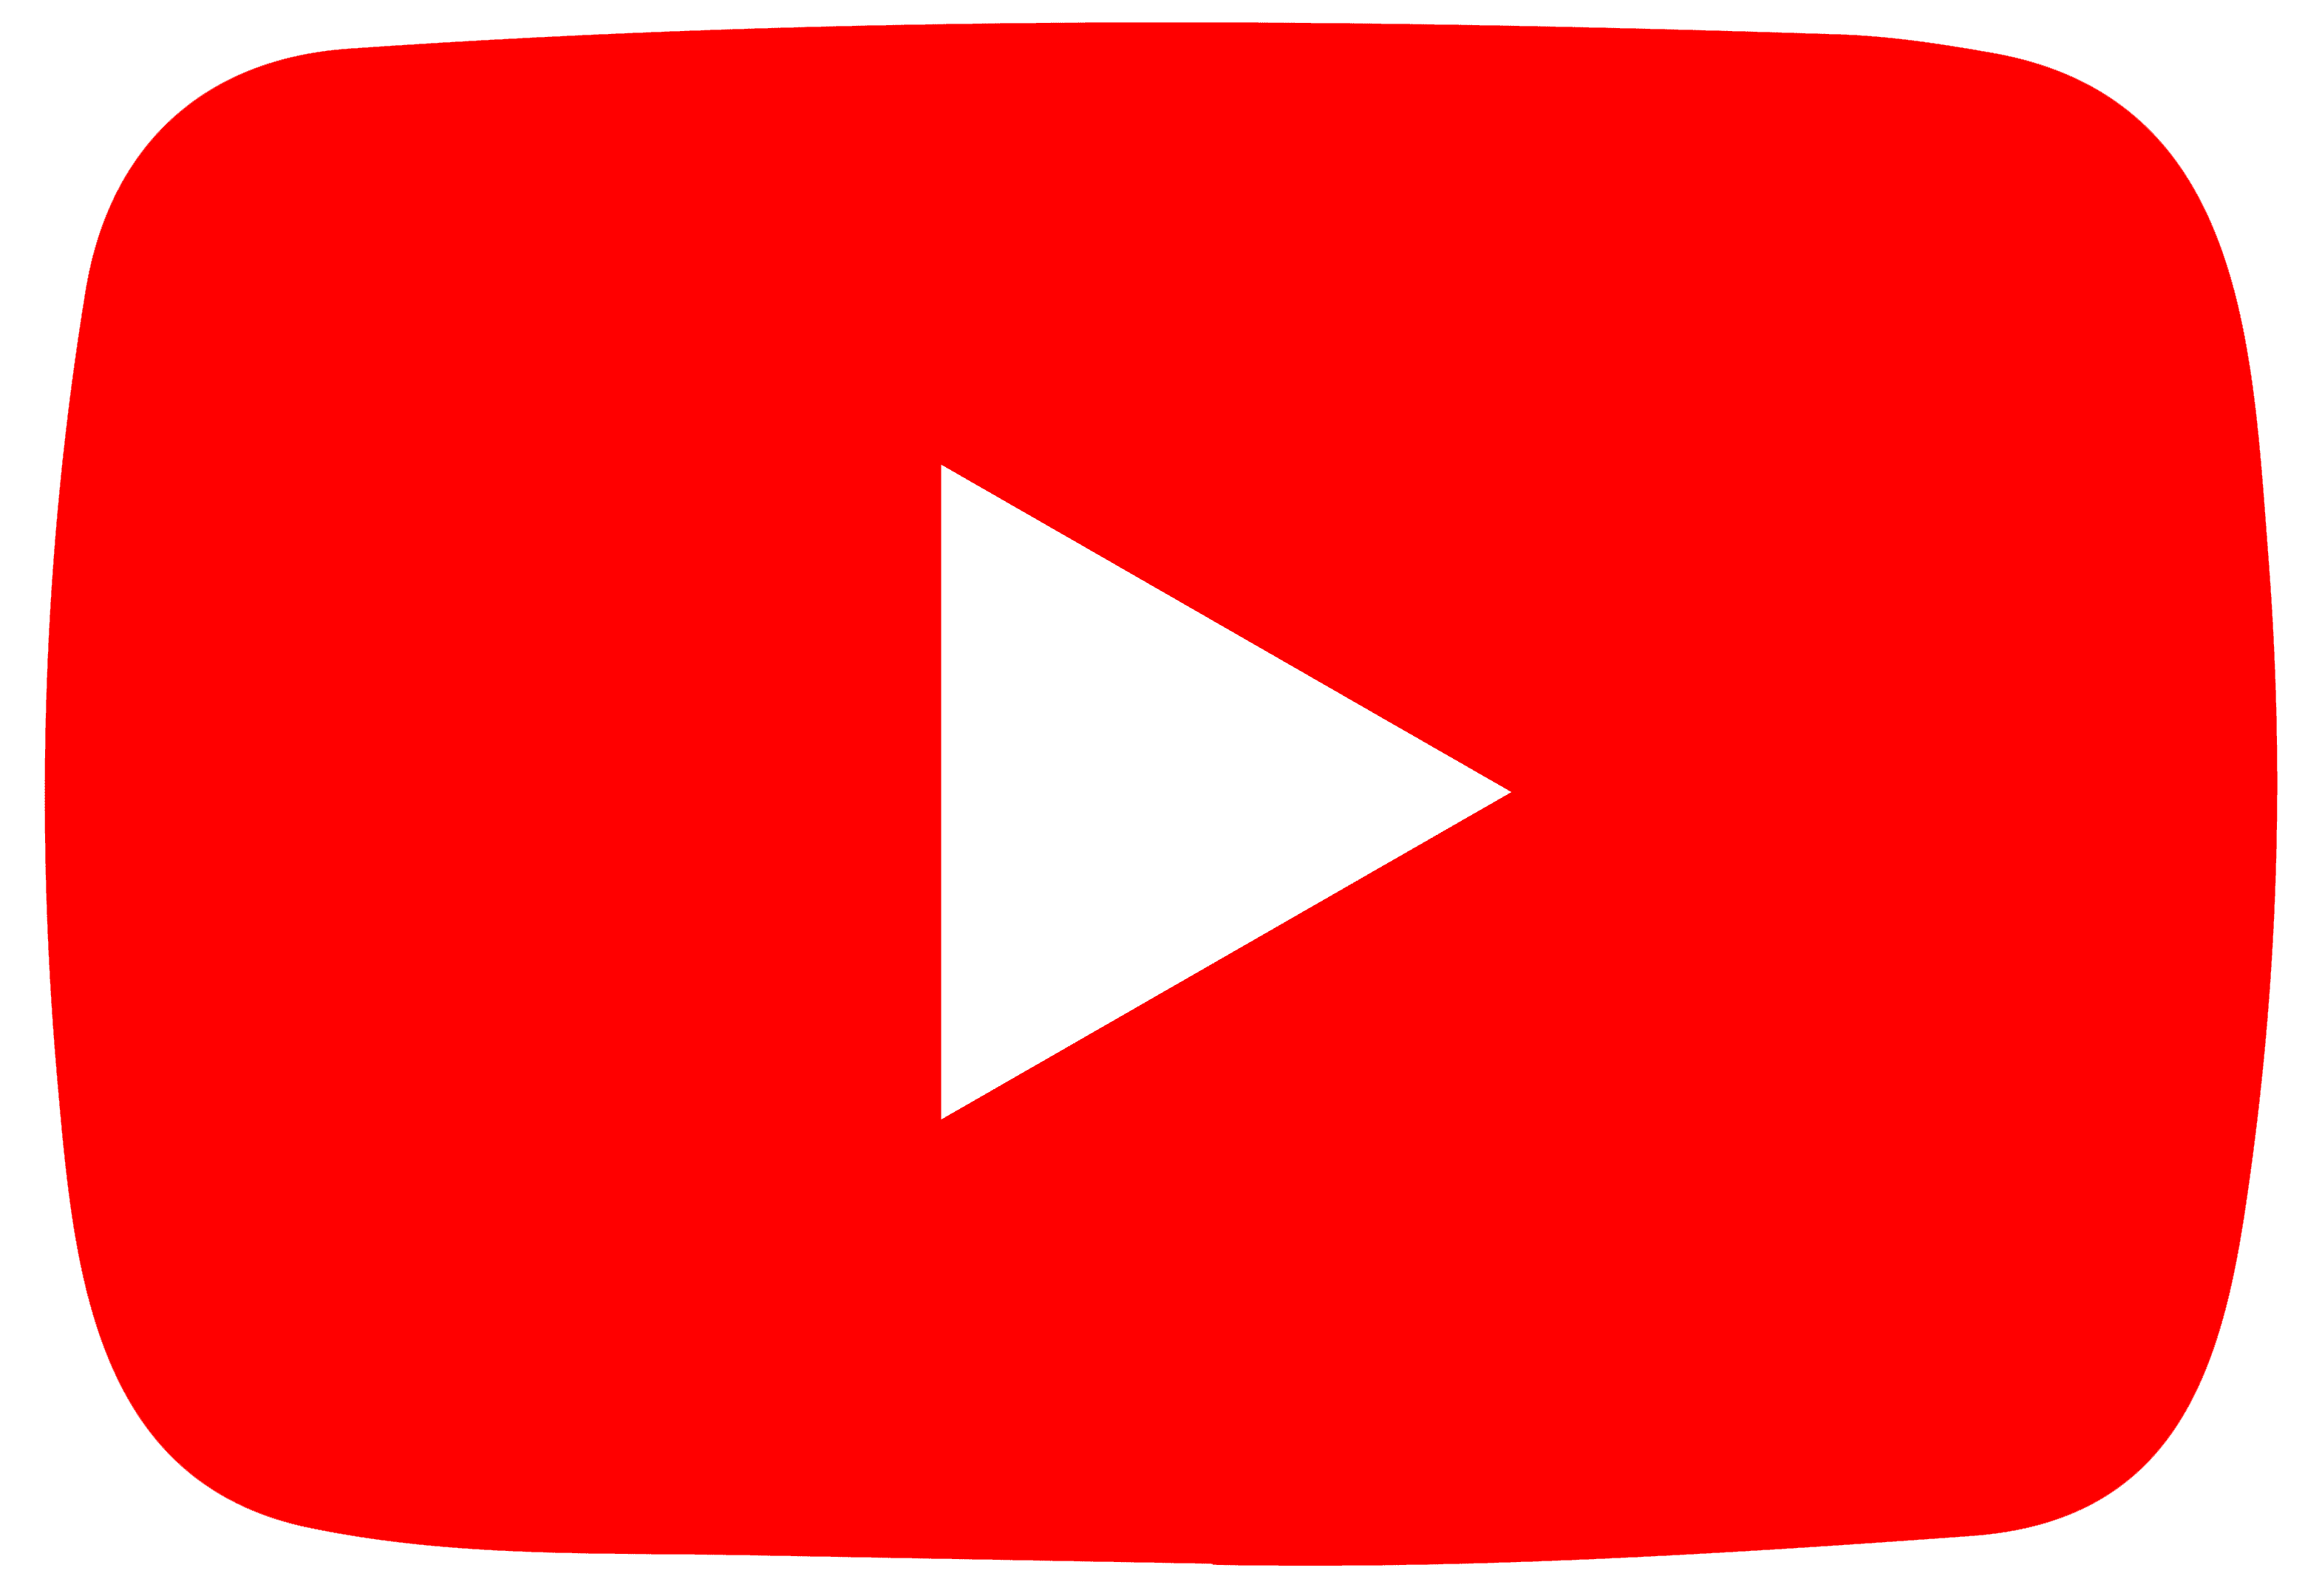 [https://www.youtube.com/user/fmglongatt](https://www.youtube.com/user/fmglongatt) 

 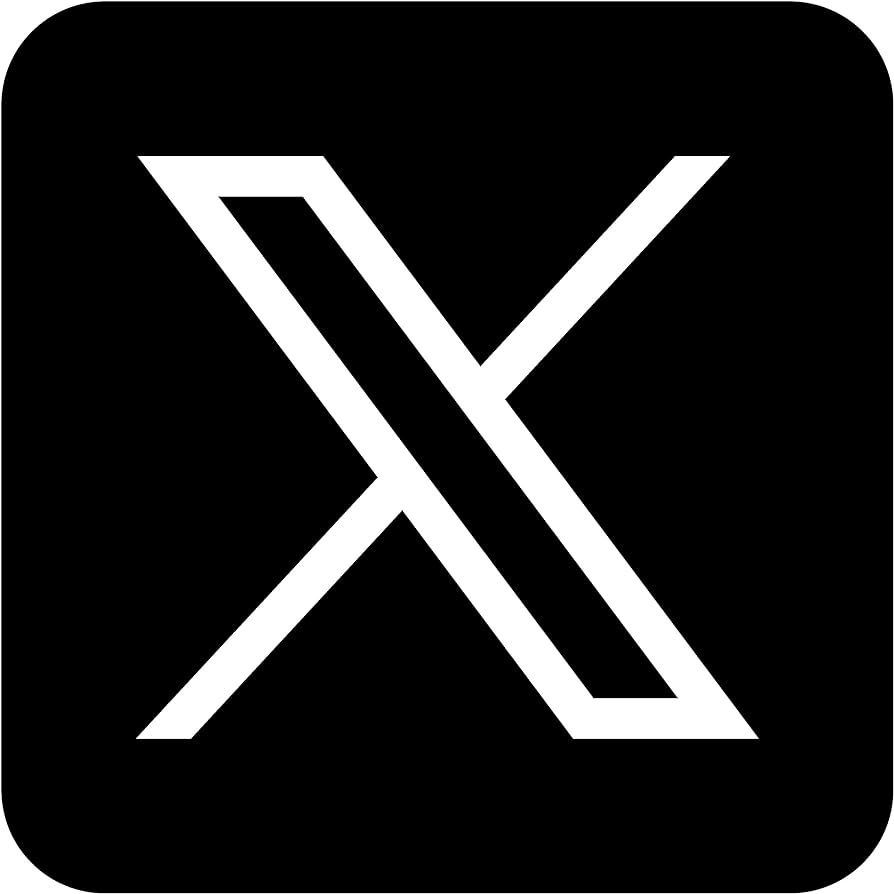  [https://twitter.com/fglongatt](https://twitter.com/fglongatt) 

 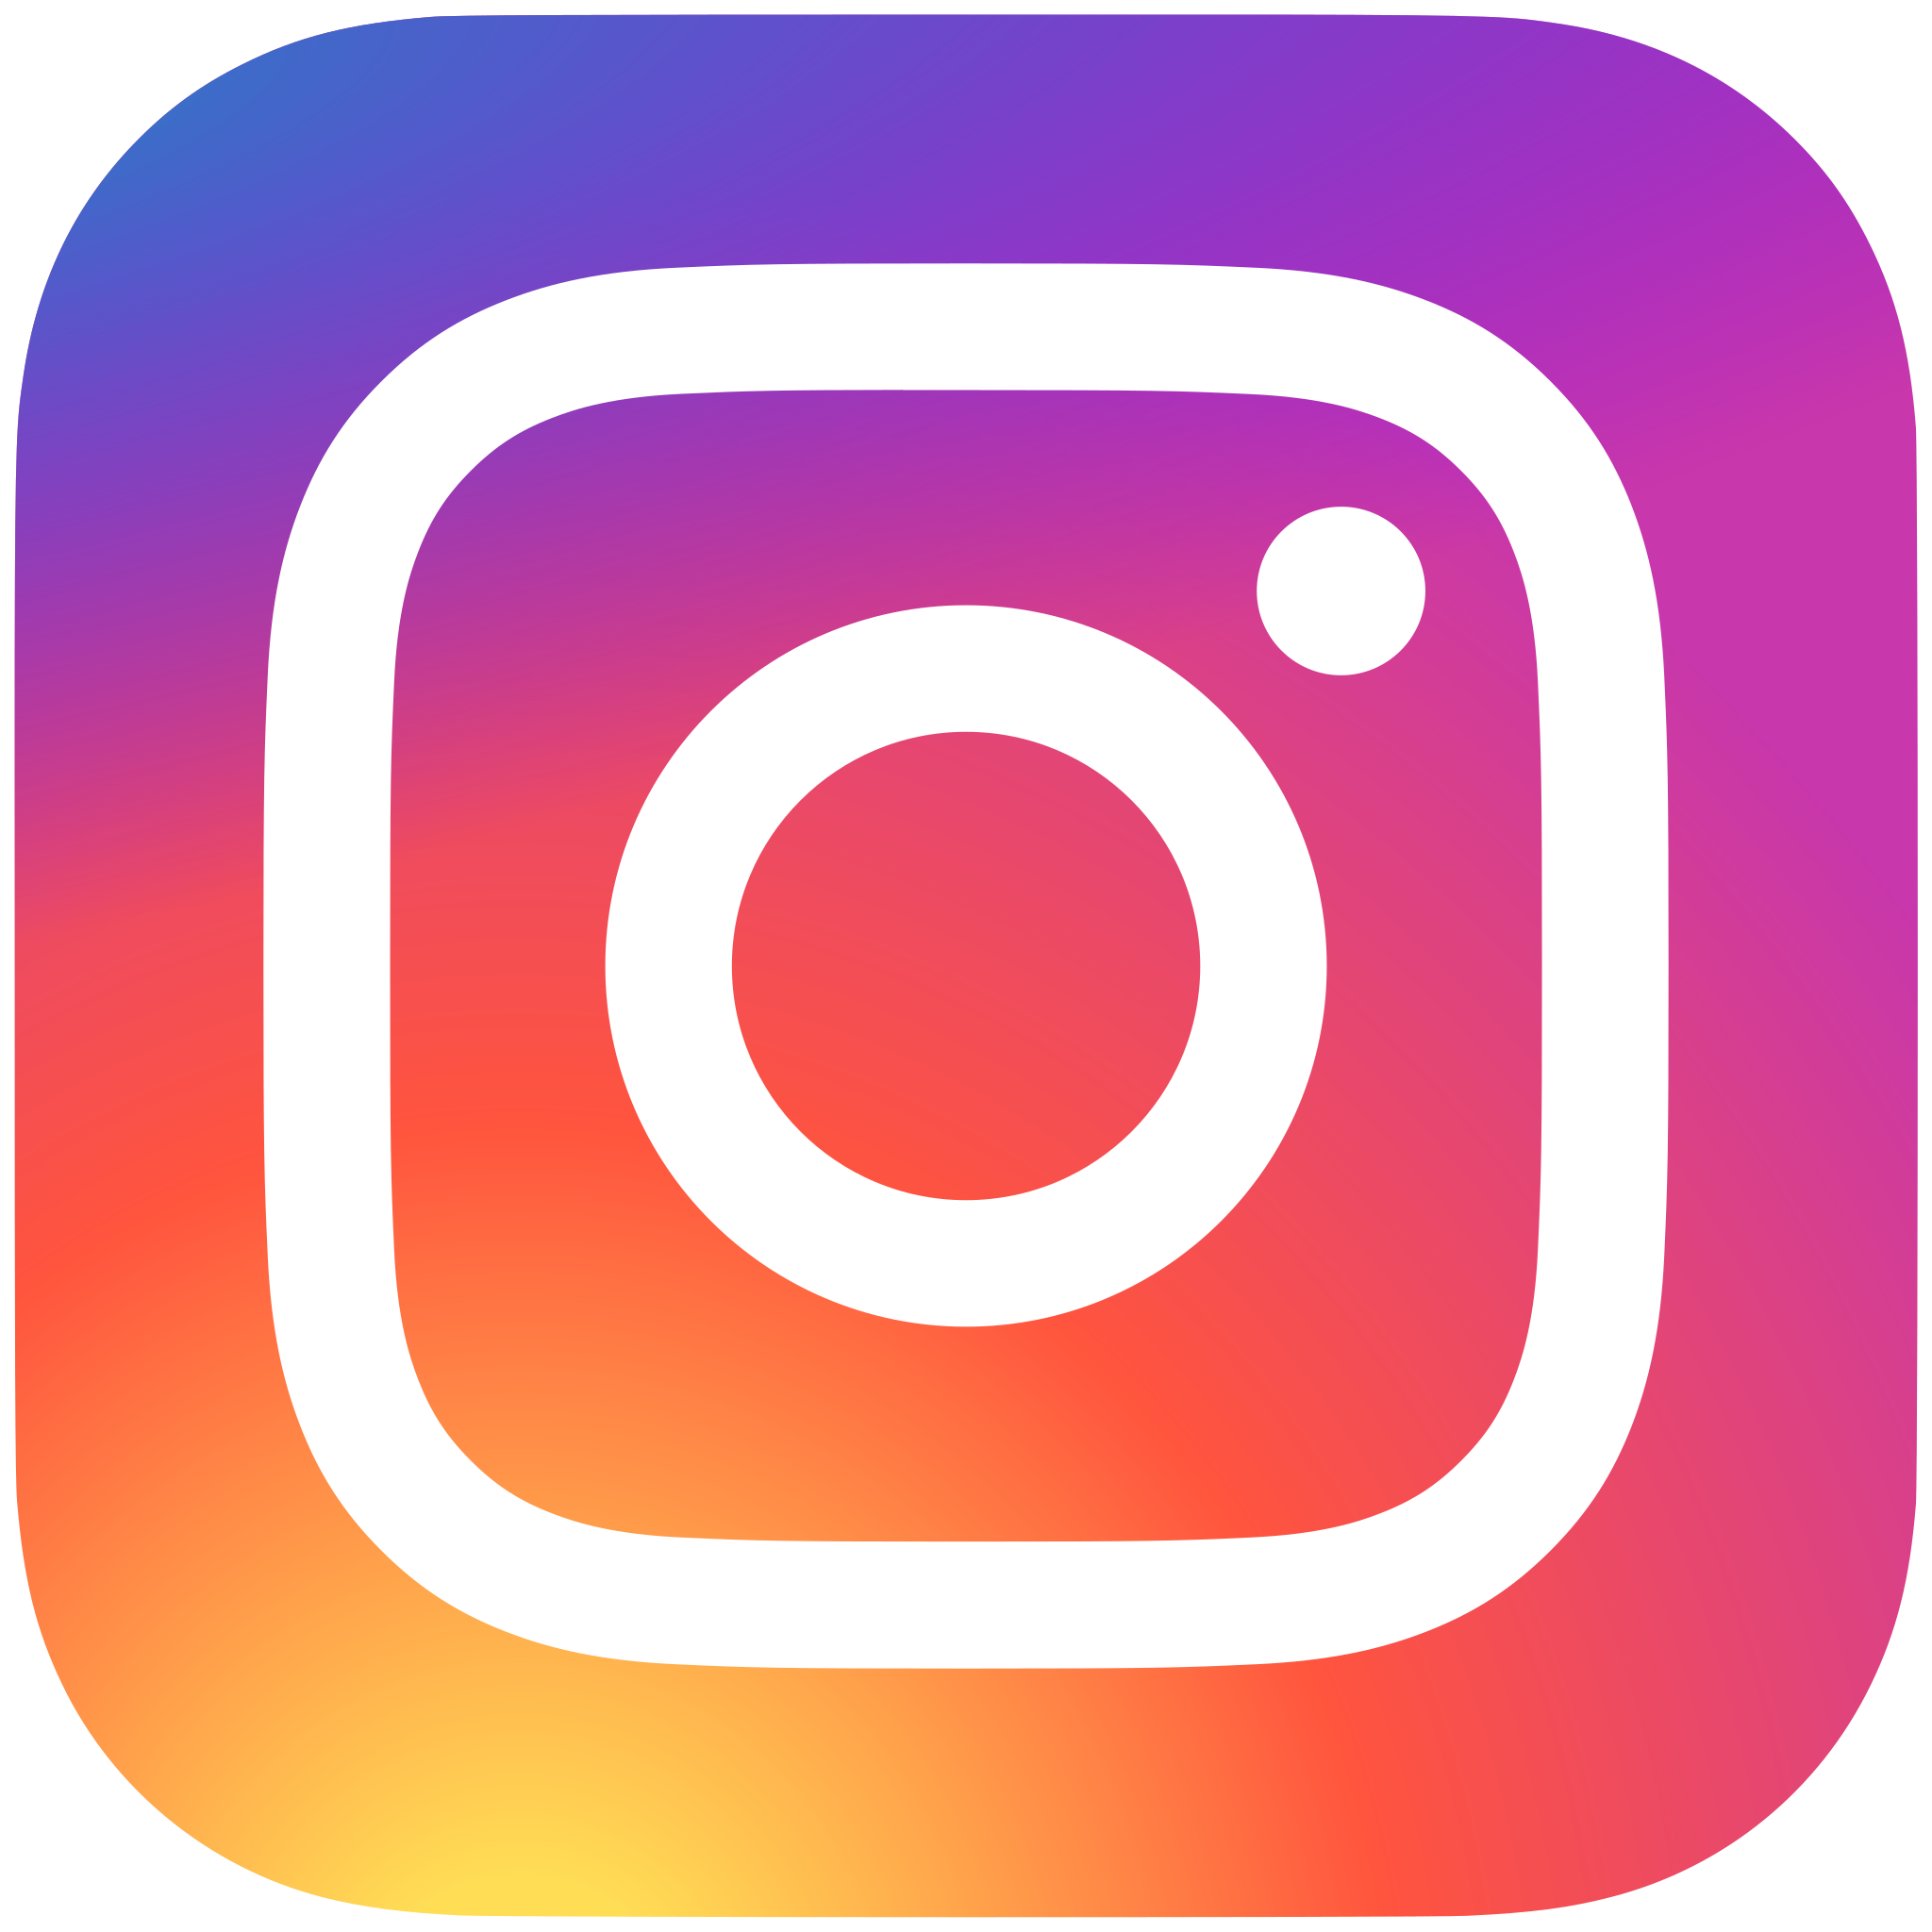 [https://www.instagram.com/fglongatt/](https://www.instagram.com/fglongatt/) 